# 酒水识别训练

初始化数据库

clc,clear,close all
dsPath="C:\Users\P1900\OneDrive\桌面\作业\数据科学\酒水识别\data\shake\train";

ads = audioDatastore(dsPath,IncludeSubfolders=true,LabelSource="foldernames");

数据增强

[adsTrain,adsValidation] = splitEachLabel(ads,0.7,0.3);

adsTrain = transform(adsTrain,@RandomNoise,'IncludeInfo',true);
adsTrain = transform(adsTrain,@BackgroundNoise,'IncludeInfo',true);


tic
[x,fileInfo] = read(adsTrain);
toc

历时 0.556351 秒。


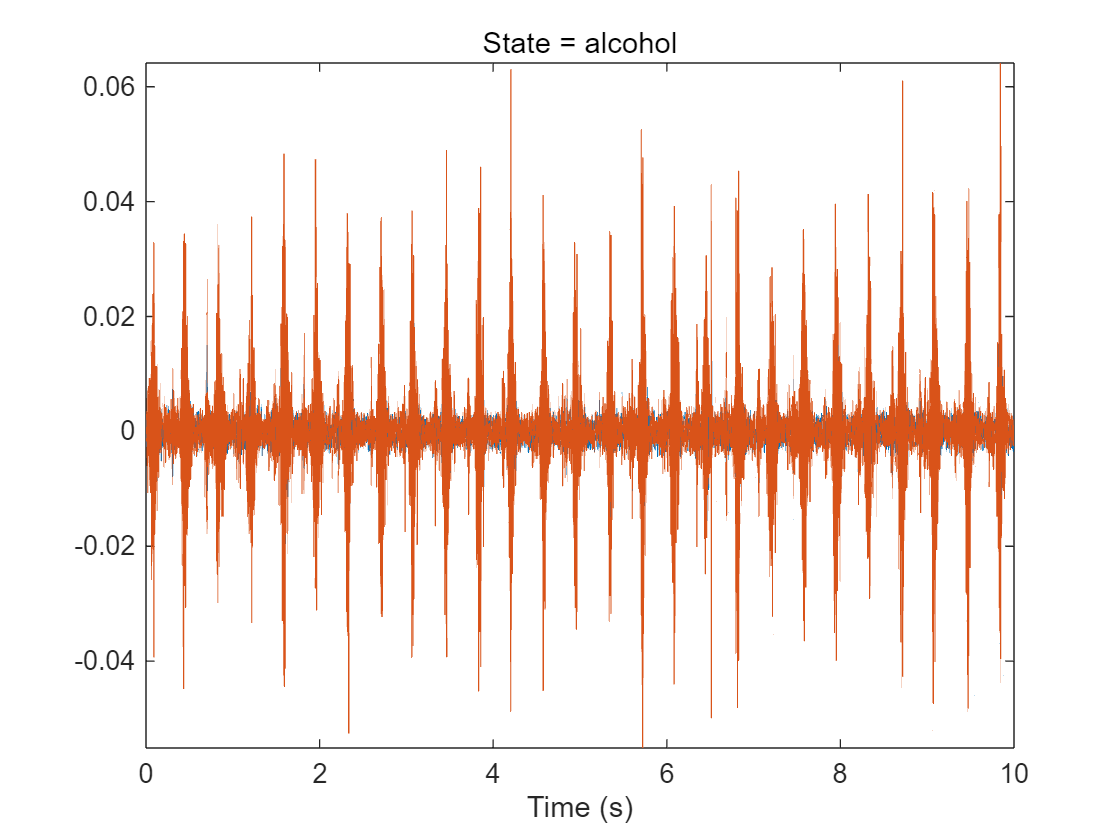

fs = fileInfo.SampleRate;
reset(adsTrain)

% sound(x,fs)

figure
t = (0:size(x,1)-1)/fs;
plot(t,x)
xlabel("Time (s)")
title("State = " + string(fileInfo.Label))
axis tight

训练集数据预处理

emptyLabelVector = ads.Labels;
emptyLabelVector(:) = [];

trainFeatures = [];
trainLabels = emptyLabelVector;

epoch=1;
while hasdata(adsTrain)
    [audioIn,fileInfo] = read(adsTrain);
    features = yamnetPreprocess(audioIn,fileInfo.SampleRate);
    numSpectrums = size(features,4);
    trainFeatures = cat(4,trainFeatures,features);
    trainLabels = cat(2,trainLabels,repmat(fileInfo.Label,1,numSpectrums));
    if ~hasdata(adsTrain) && epoch>1
        epoch=epoch-1;
        reset(adsTrain)
    end
end

验证集数据预处理

validationFeatures = [];
validationLabels = emptyLabelVector;
while hasdata(adsValidation)
    [audioIn,fileInfo] = read(adsValidation);
    features = yamnetPreprocess(audioIn,fileInfo.SampleRate);
    numSpectrums = size(features,4);
    validationFeatures = cat(4,validationFeatures,features);
    validationLabels = cat(2,validationLabels,repmat(fileInfo.Label,1,numSpectrums));
end

修改YAMNet的输出

classNames = unique(ads.Labels);
numClasses = numel(classNames);

Net = audioPretrainedNetwork("yamnet",NumClasses=numClasses);

超参数的设置

miniBatchSize = 14;
MaxEpochs=1;
LearnRateDropFactor=0.2;
InitialLearnRate=5e-5;
validationFrequency = floor(numel(trainLabels)/miniBatchSize);
options = trainingOptions('adam', ...
        InitialLearnRate=InitialLearnRate, ...
        MaxEpochs=MaxEpochs, ...
        MiniBatchSize=miniBatchSize, ...
        LearnRateSchedule="piecewise",...
        LearnRateDropPeriod=ceil(MaxEpochs/3),...
        LearnRateDropFactor=LearnRateDropFactor,...
        Shuffle="every-epoch", ...
        Metrics="accuracy", ...
        Verbose=true, ...
        Plots="training-progress",...
        ValidationData={single(validationFeatures),validationLabels'}, ...
        ValidationFrequency=validationFrequency,...
        ValidationPatience=3);

训练

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:01        5e-05                           0.76207                                    41.494
            1        1       00:00:01        5e-05         0.70325                                42.857                      
           50        1       00:00:22        5e-05         0.02823                                   100                      
           97        1       00:00:39        5e-05        0.059817           0.32159                 100                98.046
训练已停止: 已完成最大轮数


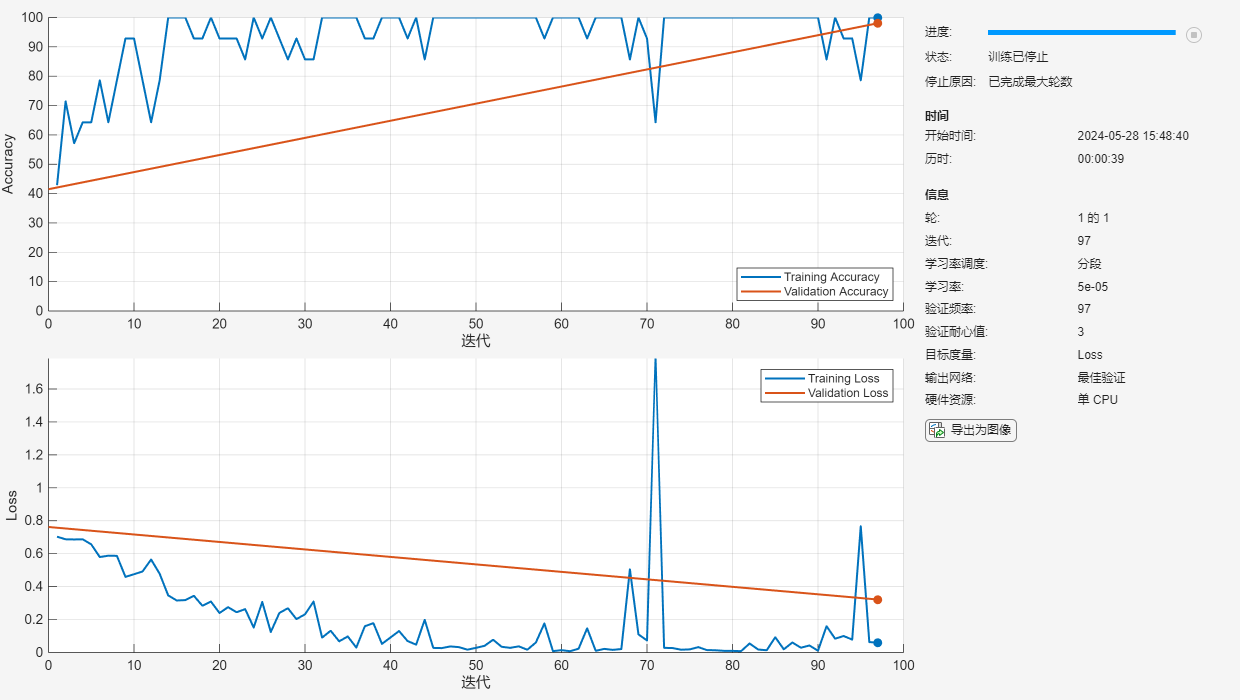

net = trainnet(trainFeatures,trainLabels',Net,"crossentropy",options);

save net.mat net 